# Tutorial 8: Workspace Analysis (Part 2: Workspace Plotting)

This tutorial will show how workspace analysis can be run in CASPR for cable-driven robots. This tutorial will use the ideas from the following previous tutorials:

- `T1_load_robot.mlx`

- `T8_workspace_analysis_1.mlx`

Part 2 of this tutorial will focus on using the `PointWorkspaceSimulator` to compute and plot the workspace for 3 DoF and higher DoF cable-driven robots.

clear;

## 3 DoF robot

### Load the robot 

Load the 3 DoF robot as shown in `T1_load_robot.mlx`. 

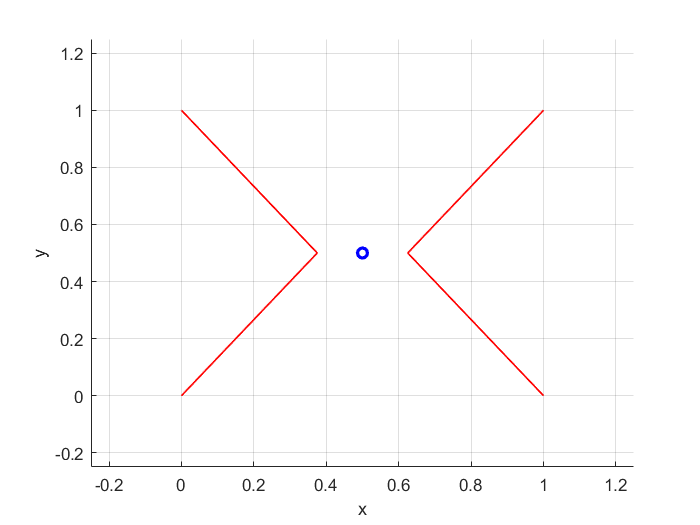

config_planar_3dof = ModelConfig('Example planar XY');
model_planar_3dof = config_planar_3dof.getModel('basic');
MotionSimulatorBase.PlotFrame(model_planar_3dof, config_planar_3dof.displayRange, config_planar_3dof.viewAngle); % Plot robot

### Setup the point-wise grid

A uniform (equal spacing) grid will be setup representing the set of points which the workspace analysis will be run.

% Set up the workspace simulator
% First the grid
q_min           = [0.02; 0.02; -pi/4];
q_max           = [0.98; 0.98; pi/4];
% q_step          = [0.02; 0.02; pi/20]; 
q_step = (q_max - q_min)/5;
uniform_grid    = UniformGrid(q_min, q_max, q_step, 'step_size');

### Wrench-feasible workspace analysis

Setup the desired wrench set:

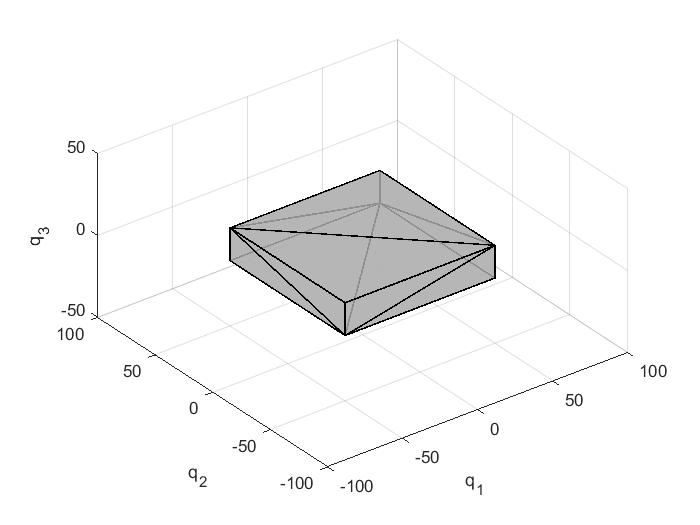

desired_wrench_set_vertices = diag([50 50 10])*[-1 -1 -1 -1  1  1  1  1; ...
                                                -1 -1  1  1 -1 -1  1  1; ...
                                                -1  1 -1  1 -1  1 -1  1];
desired_wrench_set = ConvexPolytope(desired_wrench_set_vertices);
desired_wrench_set.plotConvexPolytope([-100 100 -100 100 -50 50]);

Setup the wrench-feasible condition:

ws_condition_3dof = WrenchFeasibleCondition(desired_wrench_set, WrenchFeasibleMethodType.M_CAPACITY_MARGIN);

Create the simulator object using the robot model, grid and workspace condition:

ws_sim_3dof = PointWorkspaceSimulator(model_planar_3dof, uniform_grid, {ws_condition_3dof}, [], []);

Run the simulator over the specified grid:

ws_sim_3dof.run();

[INFO] Workspace point 1. Completion Percentage: 0.46
[INFO] Workspace point 2. Completion Percentage: 0.93
[INFO] Workspace point 3. Completion Percentage: 1.39
[INFO] Workspace point 4. Completion Percentage: 1.85
[INFO] Workspace point 5. Completion Percentage: 2.31
[INFO] Workspace point 6. Completion Percentage: 2.78
[INFO] Workspace point 7. Completion Percentage: 3.24
[INFO] Workspace point 8. Completion Percentage: 3.70
[INFO] Workspace point 9. Completion Percentage: 4.17
[INFO] Workspace point 10. Completion Percentage: 4.63
[INFO] Workspace point 11. Completion Percentage: 5.09
[INFO] Workspace point 12. Completion Percentage: 5.56
[INFO] Workspace point 13. Completion Percentage: 6.02
[INFO] Workspace point 14. Completion Percentage: 6.48
[INFO] Workspace point 15. Completion Percentage: 6.94
[INFO] Workspace point 16. Completion Percentage: 7.41
[INFO] Workspace point 17. Completion Percentage: 7.87
[INFO] Workspace point 18. Completion Percentage: 8.33
[INFO] Workspace po

### Plotting the workspace

First, plot the complete 3-D workspace:

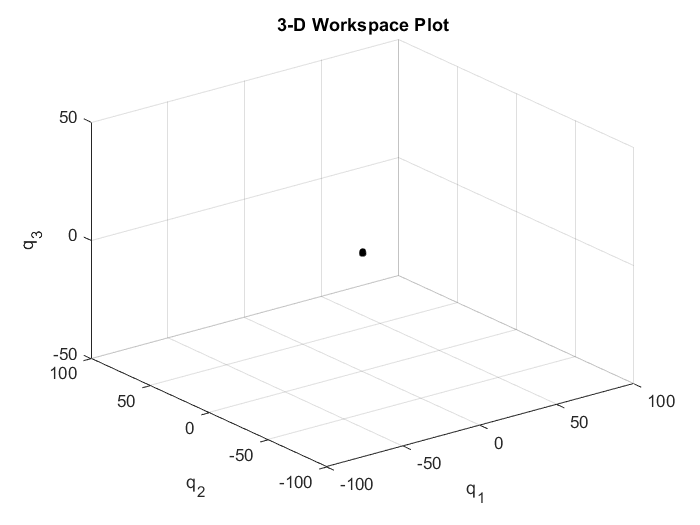

ws_sim_3dof.workspace.plotWorkspace([1 2 3]);

By default, the plot function uses the `q_min` and `q_max` values from the `bodies.xml` XML file. However, users can also specify the axis limits they would like to plot in the format of `[x_min x_max y_min y_max] `or `[x_min x_max y_min y_max z_min z_max]` for 2-D or 3-D plots, respectively:

% ws_sim_3dof.workspace.plotWorkspace([1 2 3], [], [], [0 1 0 1 -0.8 0.8]);

In addition to the 3-D workspace, it is possible to plot 2-D cross sections of the workspace. The indices [1 2] specify to plot the q_1 vs q_2 cross-section for q_3 = 0:

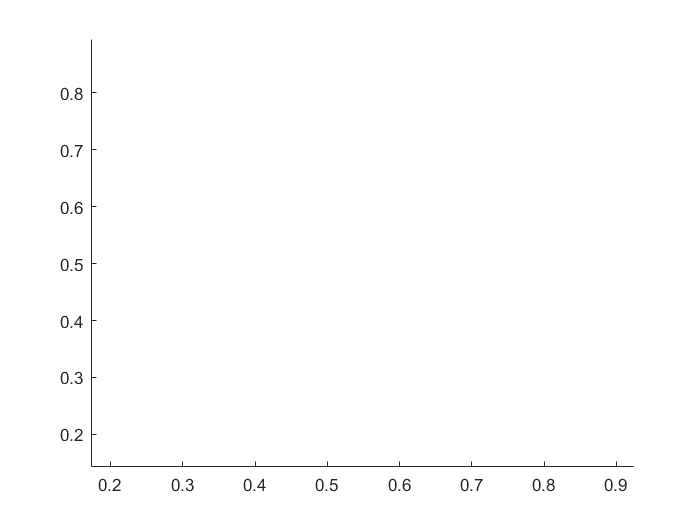

[WARNING] There are no points for this workspace to plot


figure
ws_sim_3dof.workspace.plotWorkspace([1 2], [], [], [0; 0; 0]);

The q_1 vs q_2 cross-section for q_3 = pi/20:

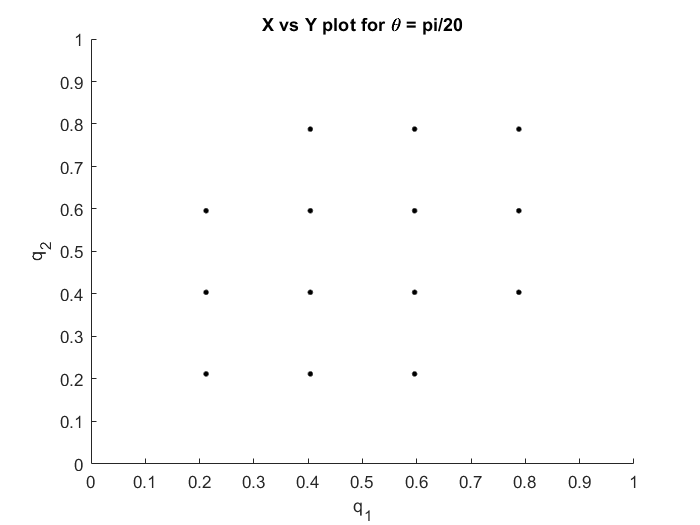

figure
ws_sim_3dof.workspace.plotWorkspace([1 2], [], [], [0; 0; pi/20]);
title('X vs Y plot for \theta = pi/20');

The q_1 vs q_2 cross-section for q_3 = pi/10:

figure
ws_sim_3dof.workspace.plotWorkspace([1 2], [], [], [0; 0; 2*pi/20]);

[WARNING] There are no points for this workspace to plot


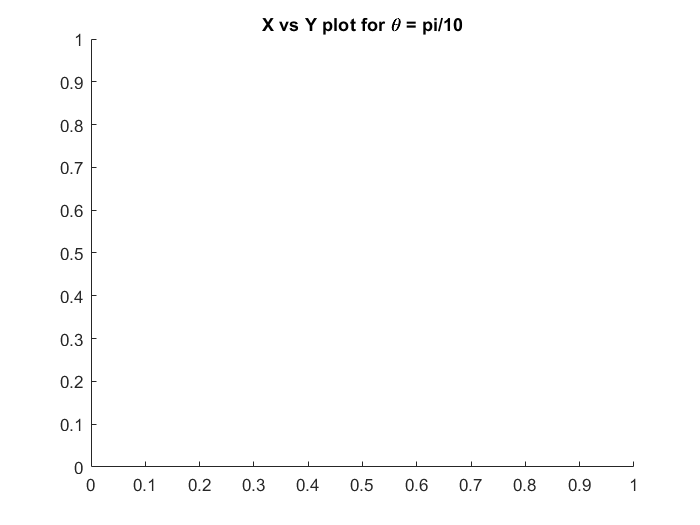

title('X vs Y plot for \theta = pi/10');

The q_1 vs q_2 cross-section for q_3 = -pi/20:

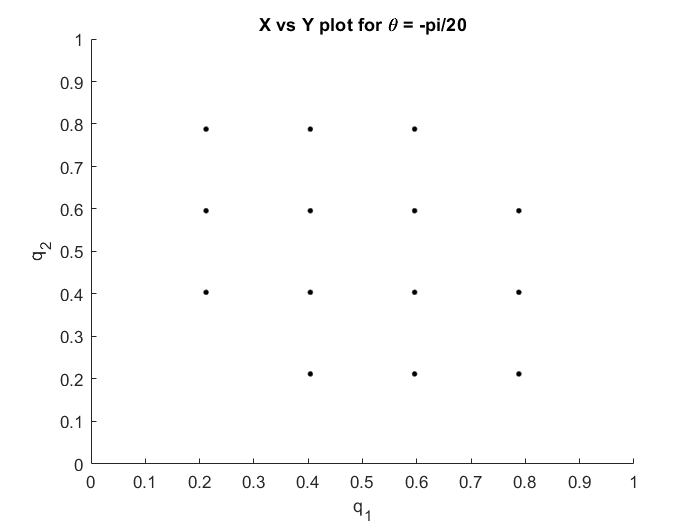

figure
ws_sim_3dof.workspace.plotWorkspace([1 2], [], [], [0; 0; -pi/20]);
title('X vs Y plot for \theta = -pi/20');

And also q_1 vs q_2 cross-section for q_3 = -pi/10:

figure
ws_sim_3dof.workspace.plotWorkspace([1 2], [], [], [0; 0; -2*pi/20]);

[WARNING] There are no points for this workspace to plot


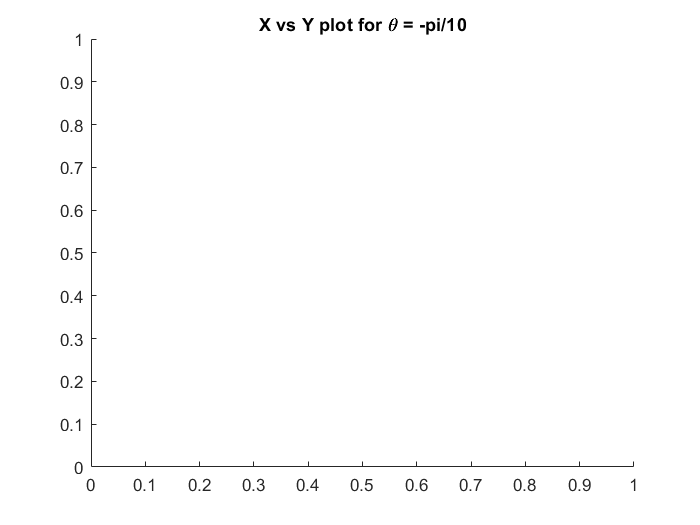

title('X vs Y plot for \theta = -pi/10');

Alternatively, the q_1 vs q_3 cross section can be plotted too:

figure
ws_sim_3dof.workspace.plotWorkspace([1 3], [], [], [0; 0.5; 0]);

[WARNING] There are no points for this workspace to plot


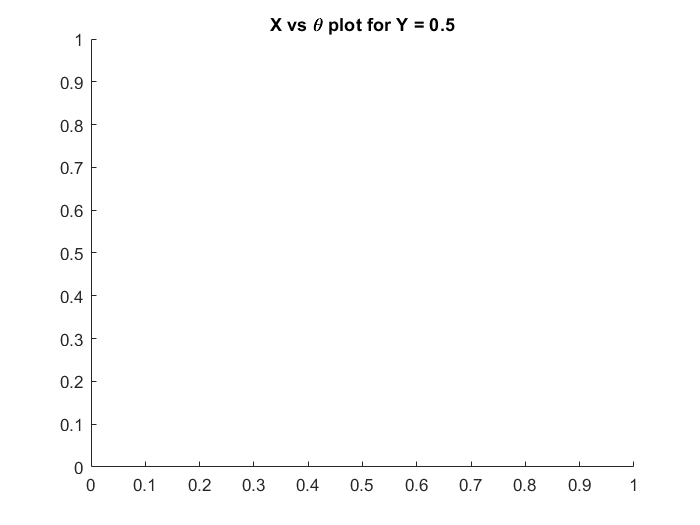

title('X vs \theta plot for Y = 0.5');

figure
ws_sim_3dof.workspace.plotWorkspace([1 3], [], [], [0; 0.8; 0]);

[WARNING] There are no points for this workspace to plot


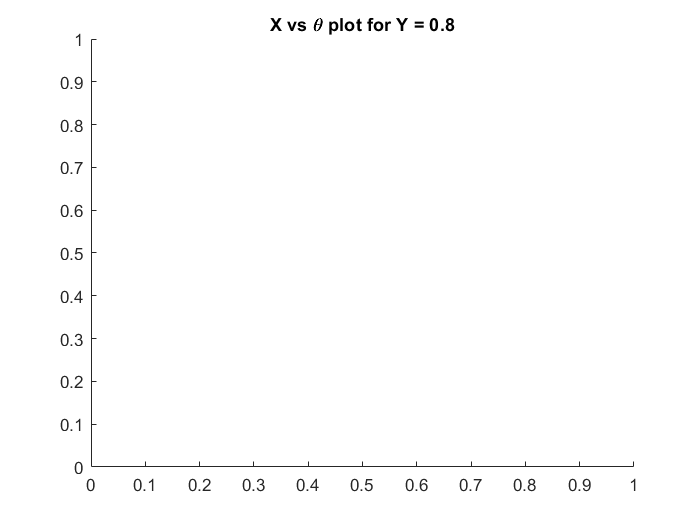

title('X vs \theta plot for Y = 0.8');

Additionally, different layer of workspace higher than 3 dimension can be plotted in 2D. Here, the workspace with the 1st condition is plotted according to different value of q_3, before that, an initiate value need to be set i.e. the 2nd value of q_3 in the grid:

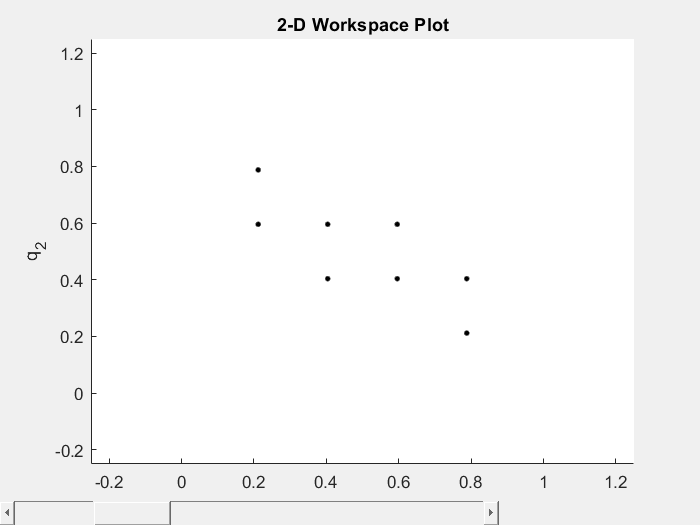

figure
sliding_axis = 3;
q_value = q_min + 1*ws_sim_3dof.grid.delta_q;
condtion_index = 1;
cartesian_workspace_plot_slide = ws_sim_3dof.workspace.plotWorkspaceSlider([1 2],sliding_axis,condtion_index, [], q_value);